data_basefolder = "H:\Data_connectome\trace_pipe_DJ";

%fill this section for input
animal = 4374;
filter_timesbg = 3; %3 is standard Guassian asssumption

%export the color-- raw pixel value
braincolor = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'pixel_raw');
if (~isfolder(braincolor))
    mkdir(braincolor);
    fprintf('making folder %s\n', braincolor);
else
    fprintf('Folder exist: %s\n', braincolor);
end

Folder exist: H:\Data_connectome\trace_pipe_DJ\4374\exported_color\brain\pixel_raw



retinacolor = fullfile(data_basefolder, string(animal), ...
    'exported_color', 'retina', 'pixel_raw');
if (~isfolder(retinacolor))
    mkdir(retinacolor);
    fprintf('making folder %s\n', retinacolor);
else
    fprintf('folder exsits %s\n', retinacolor);
end

folder exsits H:\Data_connectome\trace_pipe_DJ\4374\exported_color\retina\pixel_raw


export_spd_color(animal, true, true, braincolor);

load data... it may takes a while....
exporting color data of image 1153
exporting color data of image 1154
exporting color data of image 1155
exporting color data of image 1156
exporting color data of image 1156
exporting color data of image 1156
exporting color data of image 1156
exporting color data of image 1156
exporting color data of image 1156
exporting color data of image 1157
exporting color data of image 1158
exporting color data of image 1159
exporting color data of image 1159
exporting color data of image 1160
exporting color data of image 1161
exporting color data of image 1161
exporting color data of image 1161
exporting color data of image 1161
exporting color data of image 1162
exporting color data of image 1162
exporting color data of image 1164
exporting color data of image 1165
exporting color data of image 1165
exporting color data of image 1165
exporting color data of image 1165
exporting color data of image 1166
exporting color data of image 1166
exporting color d

export_spd_color(animal, false, true, retinacolor);

%filter through Guassian background -- brain
filtered_path = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'bg_std_filt');
if (~isfolder(filtered_path))
    mkdir(filtered_path);
end
csv_files = dir(fullfile(braincolor, '*.csv'));
num_files = length(csv_files);
br_imids = zeros([num_files, 2]);
for i = 1:num_files
    
    tokens = regexp(csv_files(i).name, ...
        '^im(\d+)_seg(\d+)_', 'tokens', 'once');
    image_id  = str2double(tokens{1});
    segNum = str2double(tokens{2});
    %image_id = str2double(image_id);
    br_imids(i, 1) = image_id;
    br_imids(i, 2) = segNum;
    t = readtable(fullfile(braincolor, csv_files(i).name));   
    %filter by 3times background frame mean

    bgfilename = sprintf('background_im%d.csv', image_id);
    bgfilepath = fullfile(braincolor, 'background', bgfilename);
    if (~isfile(bgfilepath))
        bg = get_background(image_id, true);
        bgstd = std(bg, 0, [1 2]);
        [~, ~, row, col] = size(bgstd);
        bgstd = reshape(bgstd, [row col]);
        %save a copy of the background as well
        T = array2table(bgstd, 'VariableNames',{'c1', 'c2', 'c3'});
        writetable(T,bgfilepath );
        fprintf('Saving background of image %d\n', image_id);
    else
        bgstd = table2array(readtable(bgfilepath));
        fprintf('image %d background alreday saved, loading..\n', ...
            image_id);
    end
    
    filtered = GuassianBgFlit_withT(t, bgstd,3, filter_timesbg);

    %save filtered
    wrT = array2table(filtered, 'VariableNames',{'c1', 'c2', 'c3', 'fr'});
    filtName = sprintf('im%d_seg%d_pixel_filtered.csv', image_id, segNum);
    writetable(wrT, fullfile(filtered_path, filtName));
end

Getting the background of image 1153...


Saving background of image 1153


Getting the background of image 1154...


Saving background of image 1154


Getting the background of image 1155...


Saving background of image 1155


Getting the background of image 1156...


Saving background of image 1156


image 1156 background alreday saved, loading..
image 1156 background alreday saved, loading..
image 1156 background alreday saved, loading..
image 1156 background alreday saved, loading..
image 1156 background alreday saved, loading..


Getting the background of image 1157...


Saving background of image 1157


Getting the background of image 1158...


Saving background of image 1158


Getting the background of image 1159...


Saving background of image 1159


image 1159 background alreday saved, loading..


Getting the background of image 1160...


Saving background of image 1160


Getting the background of image 1161...


Saving background of image 1161


image 1161 background alreday saved, loading..
image 1161 background alreday saved, loading..
image 1161 background alreday saved, loading..


Getting the background of image 1162...


Saving background of image 1162


image 1162 background alreday saved, loading..


Getting the background of image 1164...


Saving background of image 1164


Getting the background of image 1165...


Saving background of image 1165


image 1165 background alreday saved, loading..
image 1165 background alreday saved, loading..
image 1165 background alreday saved, loading..


Getting the background of image 1166...


Saving background of image 1166


image 1166 background alreday saved, loading..
image 1166 background alreday saved, loading..
image 1166 background alreday saved, loading..
image 1166 background alreday saved, loading..


Getting the background of image 1167...


Saving background of image 1167


image 1167 background alreday saved, loading..


Getting the background of image 1168...


Saving background of image 1168


image 1168 background alreday saved, loading..


Getting the background of image 1169...


Saving background of image 1169


Getting the background of image 1190...


Saving background of image 1190


image 1190 background alreday saved, loading..
image 1190 background alreday saved, loading..
image 1190 background alreday saved, loading..


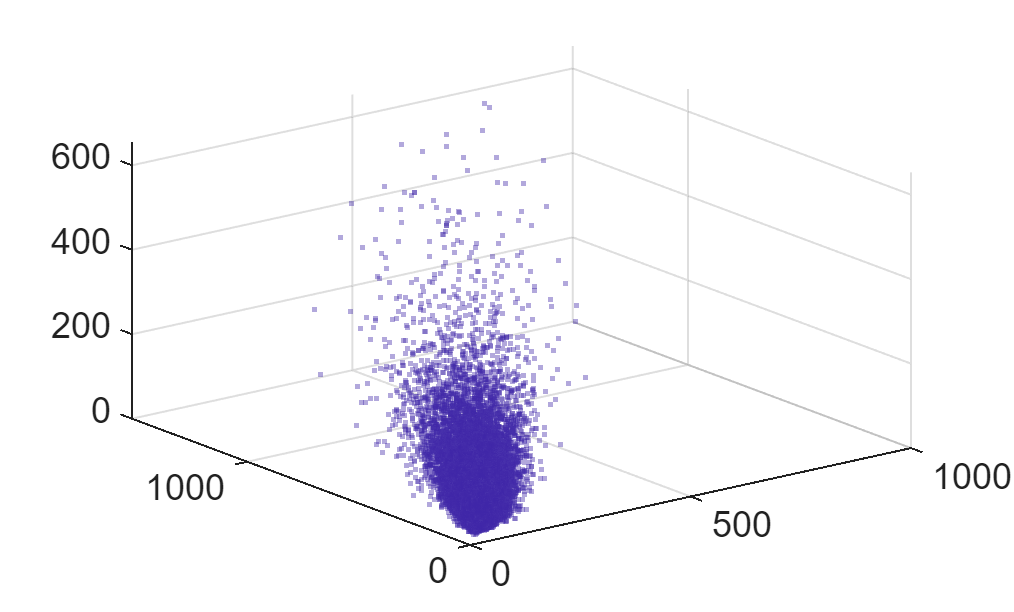

image index: 1
Press any key to continue....
image index: 2
Press any key to continue....
image index: 3
Press any key to continue....
image index: 4
Press any key to continue....
image index: 5
Press any key to continue....
image index: 6
Press any key to continue....
image index: 7
Press any key to continue....
image index: 8
Press any key to continue....
image index: 9
Press any key to continue....
image index: 10
Press any key to continue....
image index: 11
Press any key to continue....
image index: 12
Press any key to continue....
image index: 13
Press any key to continue....
image index: 14
Press any key to continue....
image index: 15
Press any key to continue....
image index: 16
Press any key to continue....
image index: 17
Press any key to continue....
image index: 18
Press any key to continue....
image index: 19
Press any key to continue....
image index: 20
Press any key to continue....
image index: 21
Press any key to continue....
image index: 22
Press any key to continue..

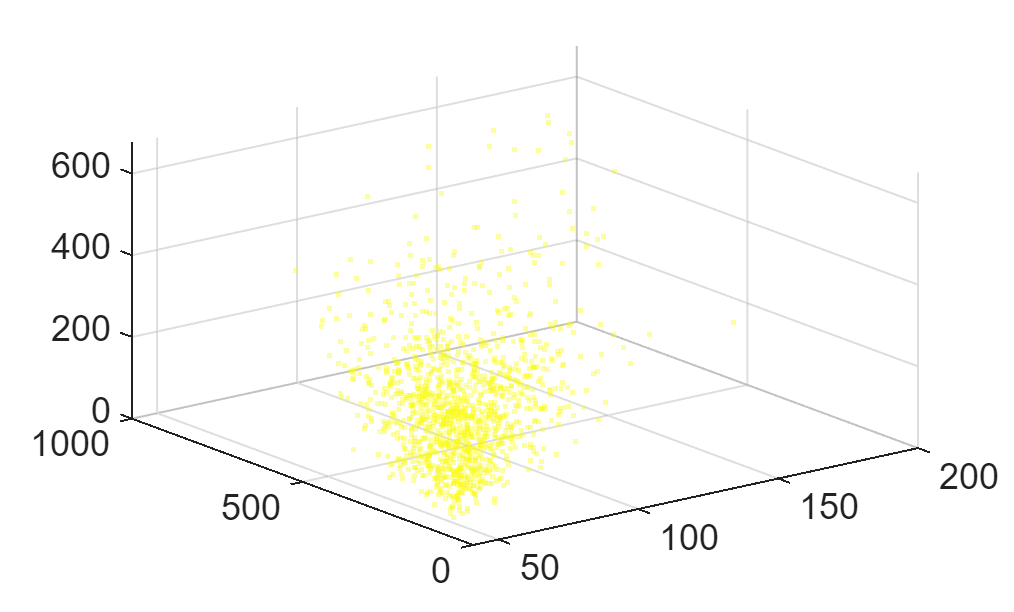

image index: 36
Press any key to continue....


%plot to see if there is splitting
%TAKE A NOTE OF THE INDEXES OF THE SPLITING PIXEL IMAGE
fig = figure;
clf(fig);
xlabel('c1');
ylabel('c2');
zlabel('c3');
colors = parula(num_files);
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:num_files
    t = readtable(fullfile(filtered_path, csv_files(i).name));
    scatter3(t.c1, t.c2, t.c3, 20, colors(i, :), '.', 'MarkerEdgeAlpha', 0.4);
    fprintf('image index: %d\nPress any key to continue....\n', i);
    % w = waitforbuttonpress;    
end

%FILL OUT THIS LIST
spliting_list = [16];
%------------------------------------------------------------------------

%spliting the pixels into 2 clusters
split_folder = fullfile(data_basefolder, string(animal), ...
    'exported_color','brain', 'brain_codeprep');
if (~isfolder(split_folder))
    mkdir(split_folder);
    fprintf('Making folder %s\n', split_folder);
end
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:numel(spliting_list)
    
    imidx = br_imids(spliting_list(i));
    fprintf('%d. dealing image %d...\n',i, imidx);
    t = readtable(fullfile(filtered_path, csv_files(spliting_list(i)).name));
    [cluster1, cluster2] = separate_2PxCluster(t);
    fig = figure;
    clf(fig);
    hold on;
    scatter(cluster1.c1, cluster1.c2);
    scatter(cluster2.c1,  cluster2.c2);
    hold off;
    fprintf('Press any key to continue...\n');

    spn1 = sprintf('%d_major_filtered.csv', imidx);
    %spn2 = sprintf('%d_minor_filtered.csv', br_imids(imidx));
    writetable(cluster1, fullfile(split_folder, spn1));
    %writetable(cluster2, fullfile(split_folder, spn2));
end

total_list = linspace(1, num_files, num_files);
non_spliting = setdiff(total_list, spliting_list);
for j = 1:numel(non_spliting)
    index = non_spliting(j);
    oldpath = fullfile(filtered_path, csv_files(index).name);
    newpath = fullfile(split_folder, csv_files(index).name);
    copyfile(oldpath, newpath);
end
fprintf('All filtered color coding files are in this folder:\n');
fprintf('%s\n', split_folder);

%filter the background retina
filtered_path = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'retina', 'bg_std_filt');
if (~isfolder(filtered_path))
    mkdir(filtered_path);
    fprintf('Made folder for retina filter\n%s\n', filtered_path);
end
csv_files = dir(fullfile(retinacolor, '*.csv'));
num_files = length(csv_files);
rt_imids = zeros([num_files, 1]);
for i = 1:num_files
    image_id = regexp(csv_files(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    rt_imids(i) = image_id;
    t = readtable(fullfile(retinacolor, csv_files(i).name));

    bg = get_background(image_id, false);

    %filter by 3times background frame mean
    bgstd = std(bg, 0, [1 2]);
    [~, ~, row, col] = size(bgstd);
    bgstd = reshape(bgstd, [row col]);

    bgfilename = sprintf('background_im%d.csv', image_id);
    %save a copy of the background as well
    T = array2table(bgstd, 'VariableNames',{'c1', 'c2', 'c3'});
    writetable(T, fullfile(retinacolor, bgfilename));

    filtered = GuassianBgFlit_withT(t, bgstd,3, filter_timesbg);

    %save filtered
    wrT = array2table(filtered, 'VariableNames',{'c1', 'c2', 'c3', 'fr'});
    filtName = sprintf('%d_rgc_pixel_filtered.csv', image_id);
    writetable(wrT, fullfile(filtered_path, filtName));
end

%plot to see if there is splitting -- RETINA
%TAKE A NOTE OF THE INDEXES OF THE SPLITING PIXEL IMAGE
fig = figure;
clf(fig);
xlabel('c1');
ylabel('c2');
zlabel('c3');
colors = parula(num_files);
csv_files = dir(fullfile(filtered_path, '*.csv'));
for i = 1:num_files
    t = readtable(fullfile(filtered_path, csv_files(i).name));
    scatter3(t.c1, t.c2, t.c3, 20, colors(i, :), '.', 'MarkerEdgeAlpha', 0.4);
    fprintf('image index: %d\nPress any key to continue....\n', i);
end

%Retina images should not have any splitting... skipping this

% %FILL OUT THIS LIST
% spliting_list = [5, 6, 8, 10];
% %------------------------------------------------------------------------
% total_list = linspace(1, num_files, num_files);
% non_spliting = setdiff(total_list, spliting_list);
% %spliting the pixels into 2 clusters
% split_folder = fullfile(data_basefolder, string(animal), ...
%     'exported_color','retina', 'retina_codeprep');
% csv_files = dir(fullfile(filtered_path, '*.csv'));
% for i = 1:numel(spliting_list)
% 
%     imidx = spliting_list(i);
%     fprintf('%d, dealing image %d...\n',i, imidx);
%     t = readtable(fullfile(filtered_path, csv_files(imidx).name));
%     [cluster1, cluster2] = separate_2PxCluster(t);
%     fig = figure;
%     clf(fig);
%     hold on;
%     scatter(cluster1.c1, cluster1.c2);
%     scatter(cluster2.c1,  cluster2.c2);
%     hold off;
%     fprintf('Press any key to continue...\n');
% 
%     spn1 = sprintf('%d_major_filtered.csv', br_imids(imidx));
%     %spn2 = sprintf('%d_minor_filtered.csv', br_imids(imidx));
%     writetable(cluster1, fullfile(split_folder, spn1));
%     %writetable(cluster2, fullfile(split_folder, spn2));
% end
% 
% %move the rest of the tables to the same folder
% for j = 1:numel(non_spliting)
%     index = non_spliting(j);
%     oldpath = fullfile(filtered_path, csv_files(index).name);
%     newpath = fullfile(split_folder, csv_files(index).name);
%     movefile(oldpath, newpath);
% end
% fprintf('All filtered color coding files are in this folder:\n');
% fprintf('%s\n', split_folder);

%---------------Filtering completed now color coding-----------------

%color coding by the most prominent features
%MOVE THE USEABLE CSV PIXEL TO THE FOLDER FIRST
codingfolder = fullfile(data_basefolder, string(animal), ...
    'exported_color', 'brain', 'brain_codeprep');
csv_files = dir(fullfile(codingfolder, '*.csv'));
num_files = numel(csv_files);
slopes = zeros(num_files, 3);
intercepts = zeros(num_files, 3);
median_br = zeros([num_files, 3]);
br_imids = zeros([num_files, 3]);
br_imids(:, 1) = linspace(1, num_files, num_files);
for i = 1:num_files
    tokens = regexp(csv_files(i).name, ...
        '^im(\d+)_seg(\d+)_', 'tokens', 'once');
    br_imids(i, 2)  = str2double(tokens{1});
    br_imids(i, 3) = str2double(tokens{2});

    t = readtable(fullfile(codingfolder, csv_files(i).name));

    model1 = fitlm(t.c1, t.c2);
    slopes(i, 1) = model1.Coefficients.Estimate(2);
    intercepts(i, 1) = model1.Coefficients.Estimate(1);
    median_br(i,1) = median(t.c1);
    
    model2 = fitlm(t.c2, t.c3);
    slopes(i, 2) = model2.Coefficients.Estimate(2);
    intercepts(i, 2) = model2.Coefficients.Estimate(1);
     median_br(i,2) = median(t.c2);

    model3 = fitlm(t.c1, t.c3);
    slopes(i, 3) = model3.Coefficients.Estimate(2);
    intercepts(i, 3) = model3.Coefficients.Estimate(1);
     median_br(i,3) = median(t.c3);

end
disp(br_imids);

           1        1153           1
           2        1154           1
           3        1155           1
           4        1156           1
           5        1156           2
           6        1156           3
           7        1156           4
           8        1156           5
           9        1156           6
          10        1157           1
          11        1158           1
          12        1159           1
          13        1159           2
          14        1160           1
          15        1161           1
          16        1161           2
          17        1161           3
          18        1161           4
          19        1162           1
          20        1162           2
          21        1164           1
          22        1165           1
          23        1165           2
          24        1165           4
          25        1166           1
          26        1166           2
          27        1166           4
 

repre2 = [slopes(:, 1:2) intercepts(:, 2)];

repre2([36, 25, 21],:) = [];

total_table = array2table([br_imids slopes intercepts]);
writetable(total_table, ...
    fullfile(data_basefolder, string(animal), 'total_features_raw.csv'));

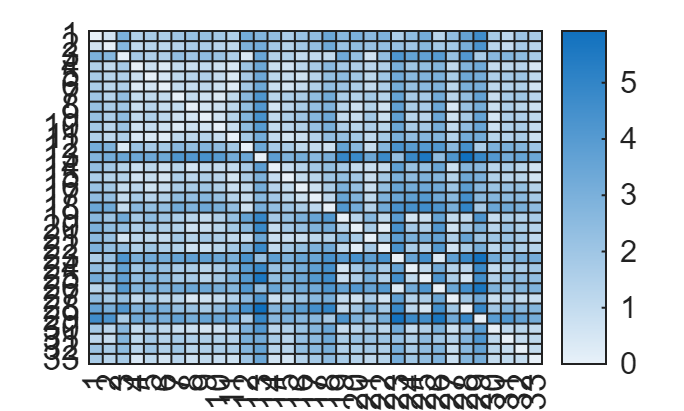

%visualize the brain axon image clusters
w = std(repre2, 0, 1);
weighted_repre2 = repre2./w;
norm_repre2 = zeros([size(repre2)]);
for i = 1:2
    norm_repre2(:, i) = z_score_norm(repre2(:, i));
end
dist = zeros([height(repre2) height(repre2)]);
for i = 1:height(repre2)
    for j = 1:height(repre2)
        dist(i,j) = norm(weighted_repre2(i, :) - weighted_repre2(j, :));
        %dist(i, j) = norm(norm_repre2(i, :) - norm_repre2(j, :));
    end
end
figure();
clf;
heatmap(dist);

clf;
scatter3(norm_repre2(:, 1), norm_repre2(:, 2), norm_repre2(:, 3), 'filled');

%save a normed repre2
total_table = array2table([br_imids norm_repre2]);
normpath = fullfile(data_basefolder, string(animal), 'normalized.csv');
writetable(total_table, normpath);

t = array2table([br_imids repre2]);
writetable(t, fullfile(data_basefolder, string(animal), 'axon_code_raw.csv'));
t = array2table([br_imids weighted_repre2]);
writetable(t, fullfile(data_basefolder, string(animal), 'axon_code_weighted.csv'));

% figure();
% hold on;
% for i = 1:height(repre2)
%     scatter3(weighted_repre2(i, 1), weighted_repre2(i, 2), ...
%         weighted_repre2(i, 3), 'filled');
%     text(weighted_repre2(i, 1), weighted_repre2(i, 2), ...
%         weighted_repre2(i, 3), string(i));
% end

figure();
hold on;
scatter3(norm_repre2(:, 1), norm_repre2(:, 2), norm_repre2(:, 3), 'filled');
for i = 1:numel(br_imids)
    text(norm_repre2(i, 1),norm_repre2(i, 2),norm_repre2(i, 3), string(br_imids(i)));
end
hold off;

%load rgc axons and color linear regression
folder_path_b = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'retina', 'retina_codeprep');
if (~isfolder(folder_path_b))
    warning('Cannot find folder-- %s\n', folder_path_b);
end
csv_files_b = dir(fullfile(folder_path_b, '*.csv'));

num_files_b = length(csv_files_b);
ret_imids = zeros([num_files_b, 1]);
slopes_b = zeros([num_files_b, 3]);
intercepts_b = zeros([num_files_b, 3]);

for i = 1:num_files_b
    file_path = fullfile(folder_path_b, csv_files_b(i).name);
    image_id = regexp(csv_files_b(i).name, '^\d+', 'match', 'once');
    image_id = str2double(image_id);
    ret_imids(i) = image_id;
    
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes_b(i, 1) =table2array(model1.Coefficients(2,1));
    intercepts_b(i, 1) = model1.Coefficients.Estimate(1);
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes_b(i, 2) = table2array(model2.Coefficients(2,1));
    intercepts_b(i, 2) = model2.Coefficients.Estimate(1);

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes_b(i, 3) = table2array(model3.Coefficients(2,1));
    intercepts_b(i, 3) = model3.Coefficients.Estimate(1);
end
repre3 = [slopes_b(:, 1:3)];

% figure();
% hold on;
% scatter3(norm_repre2(:, 1), norm_repre2(:, 2), norm_repre2(:, 3), 'filled');
% for i = 1:numel(br_imids)
%     text(norm_repre2(i, 1),norm_repre2(i, 2),norm_repre2(i, 3), string(br_imids(i)));
% end
% hold off;

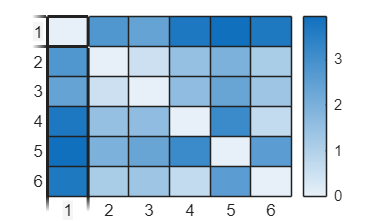

%visualize the brain axon image clusters

% w = std(repre3, 0, 1);
% weighted_repre3 = repre3./w;
norm_repre3 = zeros([size(repre3)]);
for i = 1:3
    norm_repre3(:, i) = z_score_norm(repre3(:, i));
end
distr = zeros([height(repre3) height(repre3)]);
for i = 1:height(repre3)
    for j = 1:height(repre3)
        %distr(i,j) = norm(weighted_repre2(i, :) - weighted_repre2(j, :));
        distr(i, j) = norm(norm_repre3(i, :) - norm_repre3(j, :));
    end
end
heatmap(distr);

figure();
hold on;
scatter3(norm_repre3(:, 1), norm_repre3(:, 2), norm_repre3(:, 3), 'filled');
for i = 1:numel(ret_imids)
    text(norm_repre3(i, 1),norm_repre3(i, 2),norm_repre3(i, 3), string(ret_imids(i)));
end
hold off;

%plot both types of image color coding together
fig = figure;
clf(fig);
hold on;
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3), 'magenta', 'filled');
for i = 1:num_files
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre2(i, 1), repre2(i, 2), repre2(i, 3), string(i));
end
scatter3(repre3(:, 1), repre3(:, 2),  repre3(:, 3), 'cyan', 'filled');
for i = 1:height(repre3)
    %text(repre2(i, 1), repre2(i, 2), string(i));
    text(repre3(i, 1), repre3(i, 2), repre3(i, 3), string(i));
end
grid on;
hold off;

%save the codings to csv just in case
codingFolder = fullfile(data_basefolder, string(animal), 'exported_color', ...
    'brain', 'coding');
if (~isfolder(codingFolder))
    mkdir(codingFolder);
end
filepath = fullfile(codingFolder, 'Axon_coding.csv');
t = array2table(repre2, 'VariableNames', {'f1', 'f2', 'f3'});
writetable(t, filepath);

filepath = fullfile(codingFolder, 'RGC_coding.csv');
t = array2table(repre3, 'VariableNames', {'f1', 'f2', 'f3'});
writetable(t, filepath);

repre3 = repre3(2:end, :);

ret_imids = ret_imids(2:end);

% __ MANUAL PART HERE__
%__ FILL THE AXON GROUPING
axon_grouping = { [2,3], [4, 6], [5, 7, 8, 11],[9], [10], [14, 15, 13],[16]};
Y_axon = zeros([numel(axon_grouping), 3]);
for j = 1:numel(axon_grouping)
    axonidx = axon_grouping{j};
    Y_axon(j, :) = mean(repre2(axonidx, :), 1);
end

%real match process starts
% 1. features already prepared (your step 1, raw)
%    X_rgc  : n x F  RGC features
X_rgc = repre3;
%    Y_axon : n x F  axon features      (F = 3: [s23, s13, b23])
%Y_axon = repre2;
% 2. per-feature brain-space balancing scale — COMPUTE ONCE, HERE.
w = std(Y_axon, 0, 1);          % 1 x F, spread of each feature across axons

% constraint definition (axon -> allowed RGCs)
% constr.axon = [];
% constr.rgc = [];
constr.axon = [1, 2, 3];                 % axon indices that have prior knowledge
constr.rgc = { [5, 2], [1, 6], [1, 3]};         % allowed RGC index/indices for each
% meaning: axon 2 may only match RGC 3 or 7;  axon 5 must match RGC 4


%   alternatives, pick one and keep it fixed:
%   w = median(abs(Y_axon - median(Y_axon,1)), 1) * 1.4826;   % MAD
%   w = median(Y_axon, 1);                                     % median-divide
%   (NOT ones — that's the bug you just found)

% 3. score all permutations (w threaded in, same for every permutation)
results = match_permute(X_rgc, Y_axon, w);


% 4. pick the match under sign + topographic constraints
slope_idx = [1 2];              % s23, s13 must have >=0 diagonal; b23 exempt
[best, rank_found, diag_info] = pick_match(results, constr, slope_idx);

%save results into csv
ordered_rimids = ret_imids(best.perm);
ord_cids = zeros([numel(ordered_rimids), 1]);
celltypes = {};
for i=1:numel(ordered_rimids)
    query = sprintf('image_id = %d', ordered_rimids(i));
    cellasso = fetch(sln_image.RetinalCellImage & query);
    ord_cids(i) = cellasso.cell_unid; 
    celltypes{end+1} = sln_cell.AssignType.fetch_current_type(cellasso.cell_unid);
end
grouped_axonids = {};
for i = 1:numel(axon_grouping)
    grouped_axonids{end+1} = br_imids(axon_grouping{i});
end

final_t = array2table([ordered_rimids ord_cids], 'VariableNames',{'ret_imid', 'cell_unid'});
final_t.axongrop = transpose(grouped_axonids);
final_t.celltypes = transpose(celltypes);

%save it finally!!
result_f = fullfile(data_basefolder, sprintf('%s_final_match2.csv', string(animal)));
writetable(final_t, result_f);
fprintf('result saved in %s\n', result_f);